# Add a Table to a Presentation

Use `mlreportgen.ppt.Table` objects to include tables in a presentation.

Create a presentation.

import mlreportgen.ppt.*

ppt = Presentation('myTablePresentation.pptx');
open(ppt);

slide1 = add(ppt,'Title and Table');
slide2 = add(ppt,'Title and Table');

Create a table from a cell array.

table1 = Table({'a','b';'c','d'});
table1.Children(1).FontColor = 'red';
table1.Children(2).FontColor = 'green';

Use the `find` method to find the slides that have objects with a `Name` property set to `Table`. The default  PPT API `Title and Table` layout slide has a `Table` object.

contents = find(ppt,'Table');

Replace the contents of the first slide with `table1`.

replace(contents(1),table1);

Create a second table from the output of the MATLAB® `magic` function.

table2 = Table(magic(9));

Replace the contents of the second slide with `table2`.

replace(contents(2),table2);

Close and view the presentation.

close(ppt);
rptview(ppt);

Here are the slides in the generated presentation:

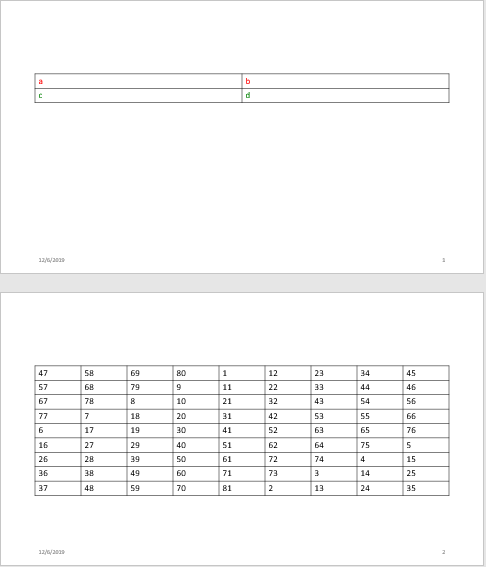

*Copyright 2019 The MathWorks, Inc.*